# PageRank - Esempio di utilizzo, test di accuratezza e di robustezza

Lo scopo di questo documento è mostrare un esempio pratico dell'utilizzo della funzione realizzata.

Di seguito vedremo come caricati nel workspace la matrice delle adiacenze `G `e il cell array `U ( `o `URL ) `contenente gli URL delle pagine di G, andremo a sviluppare il codice che implementa il soddisfacimento dei seguenti punti :

- Visualizzare un grafico che visualizza la struttura di `G` e il grafo associato;

- Visualizzare i primi 15 risultati in ordine decrescente, con i corrispondenti outdegree e indegree;

- Visualizzare un grafico a barre del `PageRank`;

- Visualizzare il sottografo costituito dai nodi con rank maggiore della media dei rank.

I passi mostrati di seguito sono stati racchiusi tutti nella funzione `pageRankSummary `che prende in ingresso il filename da cui si vogliono caricare i dati su cui effettuare le operazioni citate precedentemente.

pageRankSummary("repubblica.mat")

## **Esempio** 

Carichiamo i dati nel workspace, caricando il contenuto dal file "`repubblica.mat",`  avendo cura di eleminare le variabili precedentemente utilizzate.

clear
load repubblica.mat
% file generato utilizzando il file sufer offerto dalla docente.
% [U,G] = surfer('http://www.repubblica.it',100);

## Visualizzazione struttura di G e grafo associato

Attraverso il comando `spy`, viene visualizzata la struttura della matrice `G:`

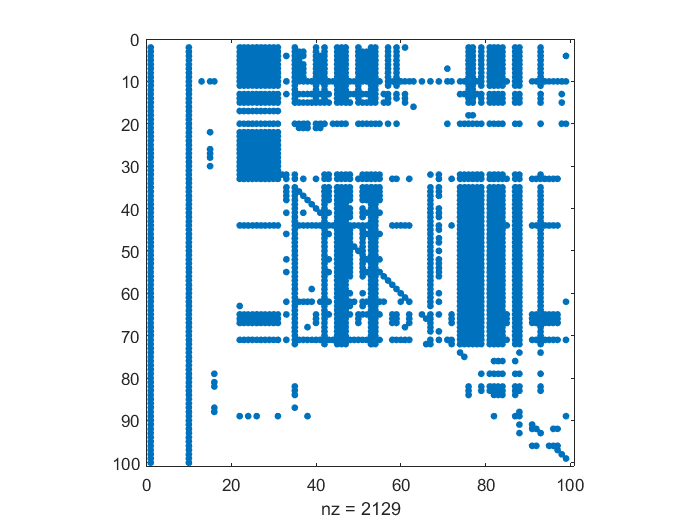

spy(G);

Partendo da G si realizza il grafo associato e lo mostriamo.

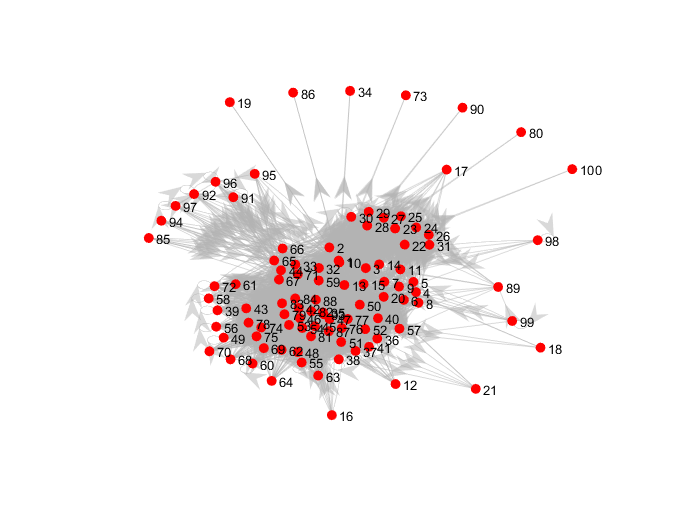

graph = digraph(G');
    
plot(graph,'NodeColor','r','EdgeColor', [.7 .7 .7],'MarkerSize',5,'ArrowSize',14); 
axis off

## Calcolo del rank con PageRank 

La funzione implementata, `PageRank,` restituisce il vettore dei rank delle pagine, gli outdegree e gli indegree. Inoltre. Successivamente all'esecuzione della funzione aggiorniamo le proprietà del grafo.

[rank, outdegree, indegree] = PageRank(G);
% Assegno le proprietà al grafo
graph.Nodes.PageRank  = rank;
graph.Nodes.InDegree  = indegree;
graph.Nodes.OutDegree = outdegree;

## Visualizzazione dei primi 15 risultati

Di seguito sono visualizzati i primi 15 risultati in ordine decrescente rispetto al rank, con i corrispondenti outdegree e indegree:

% Ordino in base al Rank
[rank, index] = sort(rank,'descend');

% Prelevo i primi 15 delle informazioni che voglio mostrare
firstSites = U(index(1:15));
ID = index(1:15);
rank = rank(1:15);
outdegree = outdegree(index(1:15));
indegree = indegree(index(1:15));

% Creo la tabella
table = table(ID,rank,outdegree,indegree,'RowNames',firstSites)

table = 15×4 table
                                                                          ID      rank      outdegree    indegree
                                                                          __    ________    _________    ________

    http://www.repubblica.it                                              10    0.093172       98           70   
    http://d.repubblica.it                                                71    0.038227        3           63   
    http://www.repubblica.it/adagiojs/adagiorep.js                        20    0.033803        0           47   
    http://design.repubblica.it                                           44    0.027891        3           59   
    http://video.repubblica.it/home                                       7

## Visualizzare un grafico a barre del `PageRank`

Disegno l'istogramma che rappresenta il rank assegnato ad ogni URL.

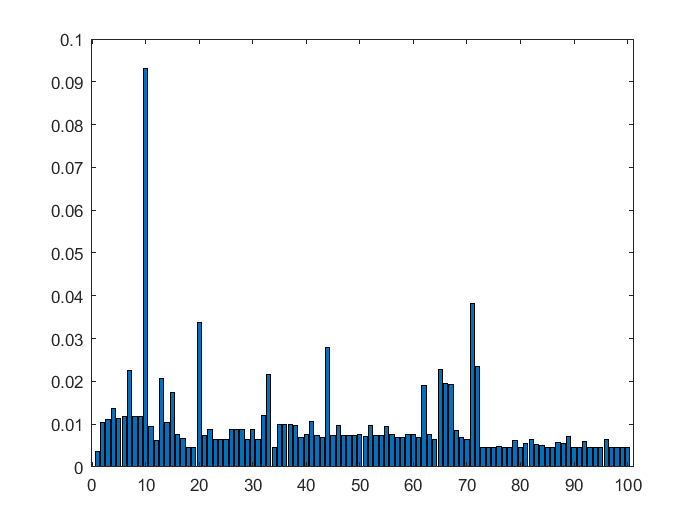

bar(graph.Nodes.PageRank); 

## Visualizzare il sottografo dei nodi con rank maggiore della media dei rank

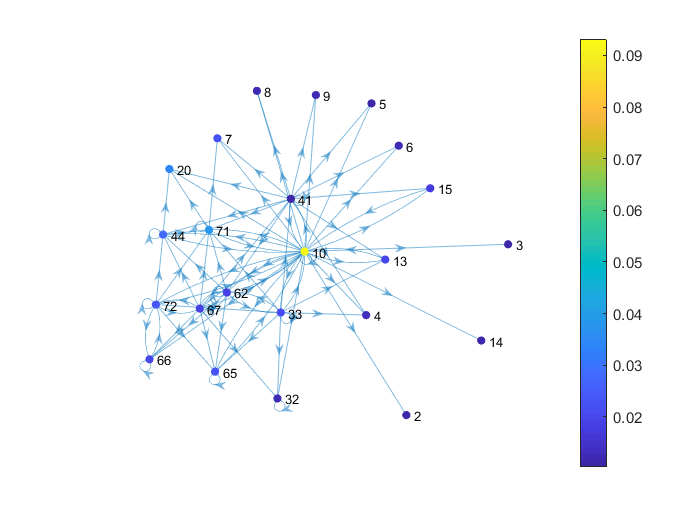

H = subgraph(graph, find(graph.Nodes.PageRank > mean(graph.Nodes.PageRank)));
plot(H,'NodeLabel',find(graph.Nodes.PageRank > mean(graph.Nodes.PageRank)),'NodeCData',...
    H.Nodes.PageRank,'Layout','force');
colorbar; 
axis off;

# Test di accuratezza

Per testare l'accuratezza dell'algoritmo implementato si confronteranno i risultati ottenuti al punto precedente con i risultati ottenuti utilizzando la funzione `centrality` [1] offerta dal Matlab. Ecco di seguito il codice necessario per ottenere una tabella avente i primi 15 risultati come visto precedentemente.

% Generazione grafo
ff = digraph(G','OmitSelfLoops');

% esecuzione dell'algoritmo pageRank
pr = centrality(ff,'pagerank','FollowProbability',0.85,'Tolerance',1e-7);

% Ordino in base al rank ottenuto
[pr, index] = sort(pr,'descend');

% Prelevo i primi 15 delle informazioni che voglio mostrare
outdegrees = ff.outdegree(index(1:15));
indegrees = ff.indegree(index(1:15));
sites = U(index(1:15));

% Creo la tabella
tableCentrality = table(index(1:15),pr(1:15),outdegrees,indegrees,'RowNames',sites,...
    'VariableNames',{'ID','rank','outdegree','indegree'})

tableCentrality = 15×4 table
                                                                          ID      rank      outdegree    indegree
                                                                          __    ________    _________    ________

    http://www.repubblica.it                                              10    0.093172       98           70   
    http://d.repubblica.it                                                71    0.038227        3           63   
    http://www.repubblica.it/adagiojs/adagiorep.js                        20    0.033803        0           47   
    http://design.repubblica.it                                           44    0.027891        3           59   
    http://video.repubblica.it/home                                   

errors = abs(pr(1:15)-rank(1:15))

errors = 	1.0e+-7 *

    0.0818
    0.0046
    0.0258
    0.0581
    0.1237
    0.0401
    0.0186
    0.0546
    0.0015
    0.0454


err    = mean(errors)

err = 3.5306e-09

Si mostra, inoltre che la media del modulo dello scarto è nell'ordine di ${10}^{-9}$ , quindi la soluzione implementata ho una buon accuratezza rispetto a quella ottenuta mediante l'utilizzo della soluzione offerta dal matlab per il calcolo del page rank

# Test di robustezza 

Per la progettazione dei casi di test è stato utilizzato il metodo di *Category-partition testing *[2]. In particolare, sono state individuate delle categorie in base ai parametri (di ingresso e uscita) modificabili dall'utente in modo tale da trovarsi nelle condizioni di errore/warning in cui la funzione si può venire a trovare.

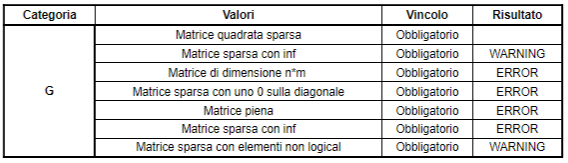

Per l'implementazione dei casi di test è stato utilizzato il framework di MatLab per il testing di unità [3]*; *questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione

results = runtests('testSuite.m')

Running testSuite
.....

.

.
Done testSuite
__________



results =   1×7 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   7 Passed, 0 Failed, 0 Incomplete.
   0.24671 seconds testing time.


Per completezza è stato progettato anche un caso di test apposito che verificasse il funzionamento dell'algoritmo in presenza di self loop, link di pagine web che si autoreferenziano. Se tenessimo conto di tali link nel calcolo del rank, queste pagine ovviamente risulterebbero con un rank alto e risulterebbero in un eventuale ricerca come le prime per importanza. Pertanto tali casi non devono essere essere considerati nel calcolo del rank; si riporta di seguito la function per il testcase implementata:

function testFunctionCase7(testCase)
% Configurazione parametri bisection_algorithm
%   - G -> valido
% Verifico che i self loop non influenzano l'esecuzione dell'algoritmo
    
    GLoop = round(sprand(10,10,0.2)*10) + spdiags(ones(10,1),0,10,10);
    G = GLoop - spdiags(G_loop,0,10,10);

    RLoop = PageRank(GLoop);
    R = PageRank(G);
   
%Il test viene effettuato verificando che il modulo della differenza tra
% il rank colcolato sul grafo in presenza di solf loop e tra il rank 
% calcolato nel caso in cui non ci siano i self loop sia minore di eps
    if abs(RLoop-R)<eps
        % passed
        verifyReturnsTrue(testCase,@true);
    else
        % not passed
        verifyReturnsTrue(testCase,@false);
    end
end

Il superamente del test numero 7 nell'esecuzione della test suite, ci permette di affermare che i risultati del calcolo del rank, mediante la funzione `PageRank,` sulle due istanza del problema, `G `(grafo senza i self loop) e  `GLoop `(grafo con i self loop), sono uguali a meno di eps.

## Riferimenti

[1] [https://it.mathworks.com/help/matlab/ref/graph.centrality.html](https://it.mathworks.com/help/matlab/ref/graph.centrality.html)

[2] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[3] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autore

Gabriele Previtera